# Model Uncertainty와 Robustness · 학습

## 실행 조건

MATLAB · Control System Toolbox

## 이번에 배울 내용

한 모델에서 설계한 제어기를 여러 실제 모델과 지연 조건에 적용해 성능이 나빠지는 지점을 찾습니다.

## 명목 모델과 실제 모델

Plant는 $m\ddot y+b\dot y+ky=u$이며, State Feedback Gain은 $K=\left[\begin{array}{cc}6&3\end{array}\right]$로 고정합니다. 질량 $m\in\{0.7,1,1.3\}$, 감쇠 $b\in\{2,3,4\}$, 강성 $k\in\{1,2,3\}$의 모든 조합을 사용하므로 검사할 모델은 $3^3=27$개입니다.

## 안정성과 성능을 따로 보기

각 모델의 Pole로 안정성을 판단하고, Step Response에서 Steady State 오차와 Settling Time을 비교합니다. 27개 조합의 성능 표는 선택한 값들에서의 결과입니다.

중간 값까지 포함한 안정성은 이 예제의 Characteristic Polynomial $ms^2+(b+3)s+(k+6)$로 판단할 수 있습니다. 2차 다항식의 세 계수가 모두 양수이면 Pole의 실수부는 음수입니다. 주어진 $m,b,k$ 구간에서는 세 계수가 모두 양수이므로 구간 전체에서 안정합니다. 응답 속도와 오차는 매개변수에 따라 달라집니다.

## MATLAB으로 같은 설계 확인하기

설계한 Gain을 고정하고 Plant의 질량·감쇠·강성만 바꿉니다. 각 조합의 Pole은 안정성을, 응답 곡선은 Overshoot와 Settling Time의 변화를 보여줍니다.

## 질량이 달라진 실제 시스템

같은 제어기를 유지하고 질량만 바꾸어 Pole과 Time Response의 차이를 비교합니다.

%% Worked example
A0=[0 1;-2 -3]; B0=[0;1]; C=[1 0]; K=place(A0,B0,[-2 -4]); N=8;
t=linspace(0,6,1201)'; figure; hold on
for m=[.7 1 1.3]
    A=[0 1;-2/m -3/m]; B=[0;1/m]; p=eig(A-B*K);
    y=lsim(ss(A-B*K,B*N,C,0),ones(size(t)),t);
    fprintf('mass %.2f\n',m); disp(p); plot(t,y,'DisplayName',sprintf('m=%g',m));
end

mass 0.70
   -1.6516
   -6.9199

mass 1.00
    -2
    -4

mass 1.30
  -2.3077 + 0.9102i
  -2.3077 - 0.9102i



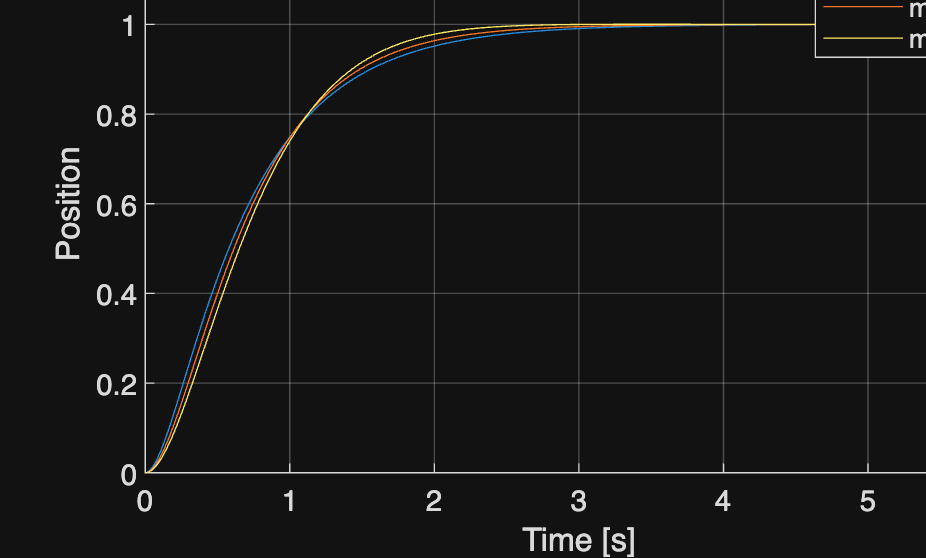

xlabel('Time [s]'); ylabel('Position'); legend; grid on

## 공식 문서·데이터

- [SciPy · Pole placement](https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.place_poles.html)